**Jan 29, 2020 Interative Matlab Bsic Operation**

**Name:** Jikhan Jeong

**Ref: **Essential Matlab for Engineers and Scientists

Ref: [https://www.mathworks.com/help/matlab/matlab_prog/live-editor-introduction.html](https://www.mathworks.com/help/matlab/matlab_prog/live-editor-introduction.html) (Interactive Matlab Editor)

- This method shows the results of code line by line like Jupternotebook

- I will use matlab for discrete choice model to change matlab code to python

- (Contorl + Alt + Enter) Code line

- (Alt + Enter) Text Line

- disp(something), print is not working in matlab command

for i = 1:5, disp(i), end

     1

     2

     3

     4

     5



** Newton's method**

a = 2;
x = a/2;
disp(['sqrt(a) for a=',num2str(a)])

sqrt(a) for a=2


for i = 1:6
    x =(a+a/x)/2;
    disp(x)
end

     2

    1.5000

    1.6667

    1.6000

    1.6250

    1.6154



disp('Lots of things to do, there is no free lunch')

Lots of things to do, there is no free lunch


disp(sqrt(2))

    1.4142



**Fatorial!**

n = 10;
fact = 1;

for k = 1:n
    fact = k*fact;
    disp([k fact])
end

     1     1

     2     2

     3     6

     4    24

     5   120

     6   720

           7        5040

           8       40320

           9      362880

          10     3628800



**If-else**

x=2;
if x<0 disp('jikhan'), else disp('handsome')
end

handsome


**Multiple ifs verse elseif**

-  rand : random number in the interval [0, 1)

bal = 15000 * rand

bal = 1.4363e+04

if bal < 5000
    rate =0.01;
    
elseif bal <10000
    rate =0.02;
    
else
    rate = 0.03;
end

disp(rate)

    0.0200



newbal = bal + rate*bal

newbal = 1.4650e+04

format bank
disp(newbal)

      14649.85



**Common Function**

sqrt([1 2 3 4])

x = -1:.1:1;

ans =           1.00          1.41          1.73          2.00


plot(x, abs(x),'o')

**Logic Operation**

- ** 0 = false, 1 = true**

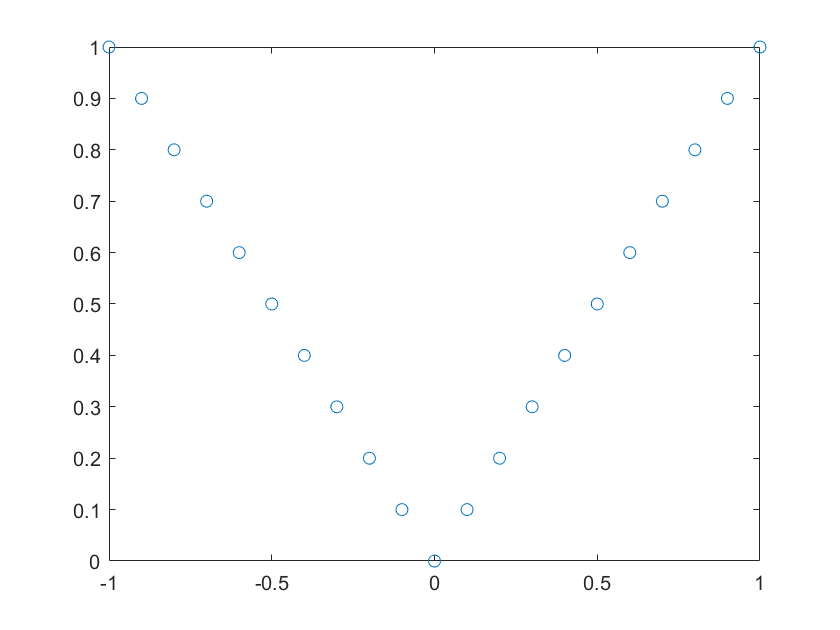

r=1;
r <= 0.5

s = 1:5;    
s <= 3

ans = logical
   0


a =   1:5;
b = [ 0 2 3 4 5];

ans = 1×5 logical array
   1   1   1   0   0


a == b

x = 0: pi/20 : 3*pi;
y = sin(x);
y = y.*(y > 0);

ans = 1×5 logical array
   0   1   1   1   1


plot(x, y)

**Elemental-Wise Matrix Product**

c = [ 1 2 3; 4 5 6; 7 8 9];
c

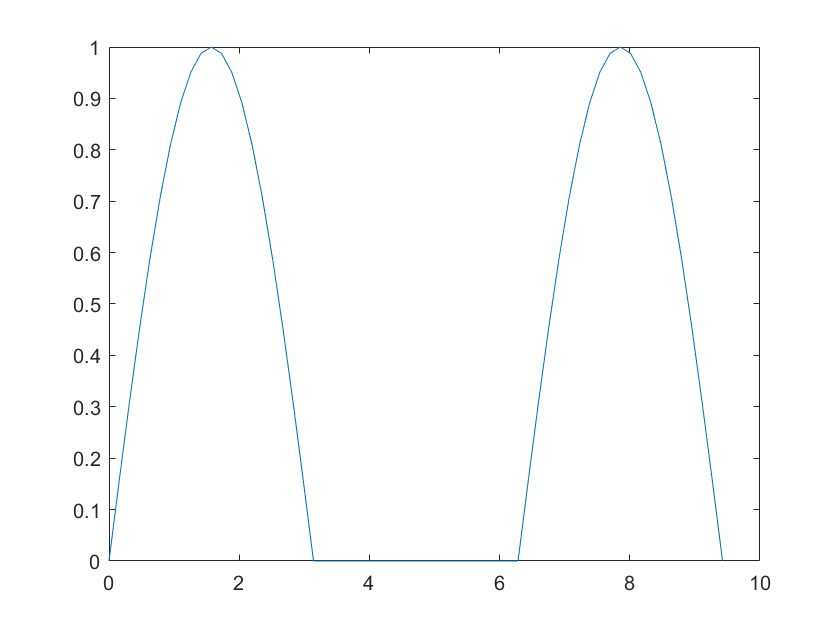

d = [1 0 0 ; 0 1 0; 0 0 1];
d

total = c.*d

a = [1 2; 3 4];
x = [5 6];

c =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


a = [a; x] % row dimension addition 

**Duplicating rows and columns**

a = [1 2 3];
b = repmat(a, [3 1])

d =           1.00             0             0
             0          1.00             0
             0             0          1.00


b(:,2)=[] % empty in column 2, remove colum 2

total =           1.00             0             0
             0          5.00             0
             0             0          9.00


** Elementary matrix**

e = eye(3) % Identity Matrix

diag(e)

a =[1 2 3; 4 5 6];

a =           1.00          2.00
          3.00          4.00
          5.00          6.00


a*2 % a*a matrix operation
a.^2 % . means element-wise operation

a =[1 2 3; 4 5 6; 7 8 9];
a

b =           1.00          2.00          3.00
          1.00          2.00          3.00
          1.00          2.00          3.00


for v = a

b =           1.00          3.00
          1.00          3.00
          1.00          3.00


    disp(v')
end


e =           1.00             0             0
             0          1.00             0
             0             0          1.00


ans =           1.00
          1.00
          1.00


ans =           2.00          4.00          6.00
          8.00         10.00         12.00


ans =           1.00          4.00          9.00
         16.00         25.00         36.00


a =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


          1.00          4.00          7.00

          2.00          5.00          8.00

          3.00          6.00          9.00

